clear all;             
f=figure;
SimEnd=2

SimEnd = 2

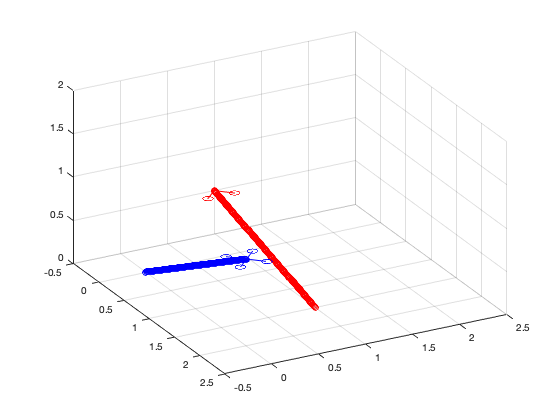

%gif('Quad.gif')
for x=0:.01:SimEnd
    cm=[x,0,x/2];        %center of mass
    bm=[1.5-x,1,x/4];    %center of mass of bogey
    CopterHandles=PlotCopter(cm,0,0,0,[0,0,1]);
    BogeyHandles=PlotCopter(bm,0,0,pi, [1,0,0]);
    view(26+15*x,29-10*x)
    %gif
    pause(.05);
    if x<SimEnd 
        for j=1:length(CopterHandles)
            delete(CopterHandles(j));
            delete(BogeyHandles(j));
        end
    end
end

function h=plotCircle3D(center,normal,radius, C)
    %this fuction plots a circle given a center, tradius and the normal vector.
    %center and normal are ROW vector
    theta=0:0.01:2*pi;
    v=null(normal);
    points=repmat(center',1,size(theta,2))+radius*(v(:,1)*cos(theta)+v(:,2)*sin(theta));
    h=plot3(points(1,:),points(2,:),points(3,:),'-', 'Color', C);
end

function h_copter=PlotCopter(cm, roll, pitch, yaw, C)

%this function draws the quadrotor.  Need to have it return the handles for cleanup.

    h_copter=[];
    l=.2;
    r=.05;
    z=[0;0;1];
    I3=eye(3);
    R=rotate(roll, pitch, yaw) ;
    norm=transpose(R*z);
   %the base quad setup at zero
    LF0=[l*cos(pi/4);l*sin(pi/4);0];
    LR0=[l*cos(3*pi/4);l*sin(3*pi/4);0];
    RR0=[l*cos(5*pi/4);l*sin(5*pi/4);0];
    RF0=[l*cos(7*pi/4);l*sin(7*pi/4);0];
    
   %Quad rotated through R matrix
    LF=[cm;[cm+transpose(R*LF0)]];
    LR=[cm;[cm+transpose(R*LR0)]];
    RR=[cm;[cm+transpose(R*RR0)]];
    RF=[cm;[cm+transpose(R*RF0)]];
    
   %plotting
    plot3(cm(1),cm(2), cm(3),"o", 'Color',C);
    view(60,10)
    grid on
    xlim([-.5, 2.5])
    ylim([-.5,2.5])
    zlim([0,2])
    hold on;
    h_copter=[h_copter;plot3(LF(:,1), LF(:,2),LF(:,3),"-", 'Color',C)];
    h_copter=[h_copter;plotCircle3D(LF(2,:), norm,r,C)];
    h_copter=[h_copter;plot3(LR(:,1), LR(:,2),LR(:,3),"-", 'Color',C)];
    h_copter=[h_copter;plotCircle3D(LR(2,:),norm,r,C)];
    h_copter=[h_copter;plot3(RR(:,1), RR(:,2),RR(:,3),"-", 'Color',C)];
    h_copter=[h_copter;plotCircle3D(RR(2,:), norm,r,C)];
    h_copter=[h_copter;plot3(RF(:,1), RF(:,2),RF(:,3),"-", 'Color',C)];
    h_copter=[h_copter;plotCircle3D(RF(2,:), norm,r,C)];
    %hold off;
end

function R=rotate(phi, theta, psi) % to give R matrix with roll pitch yaw angles
    R=[cos(theta)*cos(psi) sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi) sin(phi)*sin(psi)+cos(phi)*sin(theta)*cos(psi);
    cos(theta)*sin(psi) cos(phi)*cos(psi)+sin(phi)*sin(theta)*sin(psi) cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
    -sin(theta) sin(phi)*cos(theta) cos(phi)*cos(theta)];
end


function gif(varargin)
%Greene, Chad A., et al. "The Climate Data Toolbox for MATLAB.” 
%Geochemistry, Geophysics, Geosystems, vol. 20, no. 7, 
%American Geophysical Union (AGU), July 2019, pp. 3774–81, doi:10.1029/2019gc008392.
% gif is the simplest way to make gifs. Simply call
% 
%   gif('myfile.gif') 
% 
% to write the first frame, and then call 
% 
%   gif
% 
% to write each subsequent frame. That's it. 
% 
%% Syntax
% 
%  gif('filename.gif') 
%  gif(...,'DelayTime',DelayTimeValue,...) 
%  gif(...,'LoopCount',LoopCountValue,...) 
%  gif(...,'frame',handle,...) 
%  gif(...,'resolution',res)
%  gif(...,'nodither') 
%  gif(...,'overwrite',true)
%  gif 
%  gif('clear') 
% 
%% Description 
% 
% gif('filename.gif') writes the first frame of a new gif file by the name filename.gif. 
% 
% gif(...,'DelayTime',DelayTimeValue,...) specifies a the delay time in seconds between
% frames. Default delay time is 1/15. 
% 
% gif(...,'LoopCount',LoopCountValue,...) specifies the number of times the gif animation 
% will play. Default loop count is Inf. 
% 
% gif(...,'frame',handle,...) uses the frame of the given figure or set of axes. The default 
% frame handle is gcf, meaning the current figure. To turn just one set of axes into a gif, 
% use 'frame',gca. This behavior changed in Jan 2021, as the default option changed from
% gca to gcf.
% 
% gif(...,'resolution',res) specifies the resolution (in dpi) of each frame. This option
% requires export_fig (https://www.mathworks.com/matlabcentral/fileexchange/23629).
%
% gif(...,'nodither') maps each color in the original image to the closest color in the new 
% without dithering. Dithering is performed by default to achieve better color resolution, 
% albeit at the expense of spatial resolution.
% 
% gif(...,'overwrite',true) bypasses a dialoge box that would otherwise verify 
% that you want to overwrite an existing file by the specified name. 
%
% gif adds a frame to the current gif file. 
% 
% gif('clear') clears the persistent variables associated with the most recent gif. 
% 
%% Example 
% For examples, type 
% 
%   cdt gif
% 
%% Author Information 
% This function was written by Chad A. Greene of the University of Texas 
% Institute for Geophysics (UTIG), June 2017. 
% 
% See also: imwrite, getframe, and rgb2ind. 
% Define persistent variables: 
persistent gif_filename firstframe DelayTime DitherOption LoopCount frame resolution
%% Parse Inputs
if nargin>0 
   
   % The user may want to clear things and start over: 
   if any(strcmpi(varargin,'clear'))
            
      % Clear persistent variables associated with this function: 
      clear gif_filename firstframe DelayTime DitherOption LoopCount frame resolution
   end
   
   % If the first input ends in .gif, assume this is the first frame:
   if strcmpi(varargin{1}(end-3:end),'.gif')
      
      % This is what the user wants to call the new .gif file: 
      gif_filename = varargin{1}; 
      
      % Check for an existing .gif file by the same name: 
      if exist(gif_filename,'file')==2
         OverWrite = false; % By default, do NOT overwrite an existing file by the input name. 
         if nargin>1
            tmp = strncmpi(varargin,'overwrite',4); 
            if any(tmp)
               OverWrite = varargin{find(tmp)+1}; 
               assert(islogical(OverWrite),'Error: Overwrite input must be either true or false.')
            end
         end
         
         if ~OverWrite
         
            % Ask the user if (s)he wants to overwrite the existing file: 
            choice = questdlg(['The file  ',gif_filename,' already exists. Overwrite it?'], ...
               'The file already exists.','Overwrite','Cancel','Cancel');
            if strcmp(choice,'Overwrite')
               OverWrite = true; 
            end
         end
         
         % Overwriting basically means deleting and starting from scratch: 
         if OverWrite
            delete(gif_filename) 
         else 
            clear gif_filename firstframe DelayTime DitherOption LoopCount frame
            error('The giffing has been canceled.') 
         end
         
      end
      
      firstframe = true; 
      
      % Set defaults: 
      DelayTime = 1/15; 
      DitherOption = 'dither'; 
      LoopCount = Inf; 
      frame = gcf; 
      resolution = 0; % When 0, it's used as a boolean to say "don't use export_fig". If greater than zero, the boolean says "use export_fig and use the specified resolution."  
   end
   
   tmp = strcmpi(varargin,'DelayTime'); 
   if any(tmp) 
      DelayTime = varargin{find(tmp)+1}; 
      assert(isscalar(DelayTime),'Error: DelayTime must be a scalar value.') 
   end
   
   if any(strcmpi(varargin,'nodither'))
      DitherOption = 'nodither'; 
   end
   
   tmp = strcmpi(varargin,'LoopCount'); 
   if any(tmp) 
      LoopCount = varargin{find(tmp)+1}; 
      assert(isscalar(LoopCount),'Error: LoopCount must be a scalar value.') 
   end
   
   tmp = strncmpi(varargin,'resolution',3); 
   if any(tmp) 
      resolution = varargin{find(tmp)+1}; 
      assert(isscalar(resolution),'Error: resolution must be a scalar value.') 
      assert(exist('export_fig.m','file')==2,'export_fig not found. If you wish to specify the image resolution, get export_fig here :https://www.mathworks.com/matlabcentral/fileexchange/23629. Otherwise remove the resolution from the gif inputs to use the default (lower quality) built-in getframe functionality.')  
      warning off export_fig:exportgraphics
   end
   
   tmp = strcmpi(varargin,'frame'); 
   if any(tmp) 
      frame = varargin{find(tmp)+1}; 
      assert(ishandle(frame)==1,'Error: frame must be a figure handle or axis handle.') 
   end
   
else
   assert(isempty(gif_filename)==0,'Error: The first call of the gif function requires a filename ending in .gif.') 
end
%% Perform work: 
if resolution % If resolution is >0, it means use export_fig
   
   if isgraphics(frame,'figure')
      f = export_fig('-nocrop',['-r',num2str(resolution)]);
   else
      % If the frame is a set of axes instead of a figure, use default cropping: 
      f = export_fig(['-r',num2str(resolution)]);
   end
      
else
   % Get frame: 
   fr = getframe(frame); 
   f =  fr.cdata; 
end
% Convert the frame to a colormap and corresponding indices: 
[imind,cmap] = rgb2ind(f,256,DitherOption);    
% Write the file:     
if firstframe
   imwrite(imind,cmap,gif_filename,'gif','LoopCount',LoopCount,'DelayTime',DelayTime)
   firstframe = false;
else
   imwrite(imind,cmap,gif_filename,'gif','WriteMode','append','DelayTime',DelayTime)
end
end